% electrical constants and derived quantities for typical 
% mammalian dendrite

% Dimensions of compartments

d1 = 75e-4; 			% cm
% d21 = 30e-4; 			% cm
% d22 = 15e-4; 			% cm
d21 = 47.2470e-4;       % E9 cm
d22 = d21;               % E9 cm

l1 = 1.5;			% dimensionless
l21 = 3.0;			% dimensionless
l22 = 3.0;			% dimensionless

% Electrical properties of compartments

Rm = 6e3;			% Ohms cm^2
Rc = 90;			% Ohms cm
Rs = 1e6;			% Ohms

c1 = 2*(Rc*Rm)^(1/2)/pi;

rl1 = c1*d1^(-3/2);		% Ohms
rl21 = c1*d21^(-3/2);		% Ohms
rl22 = c1*d22^(-3/2);		% Ohms


% Applied current

iapp = 1e-9; 	% Amps

% Coefficient matrices

A = [1 -1 0 0 0 0;
     0 0 exp(-l21) exp(l21) 0 0;
     0 0 0 0 exp(-l22) exp(l22);
     exp(-l1) exp(l1) -exp(-l1) -exp(l1) 0 0;
     0 0 exp(-l1) exp(l1) -exp(-l1) -exp(l1);
     -exp(-l1) exp(l1) rl1*exp(-l1)/rl21 -rl1*exp(l1)/rl21 rl1*exp(-l1)/rl22 -rl1*exp(-l1)/rl22];

b = [rl1*iapp 0 0 0 0 0]';

# Question 3

x = A\b;
display(x)

x = 	1.0e+-3 *

    0.7189
   -0.0014
    0.7275
   -0.0018
    0.7275
   -0.0018


# Question 4

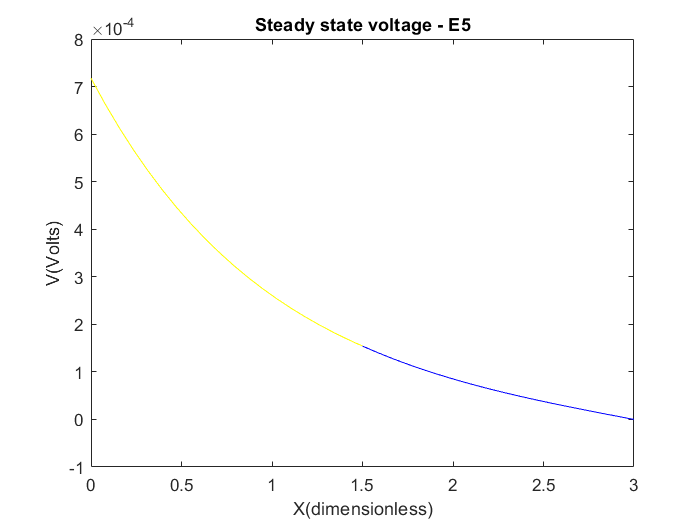

y1=linspace(0,l1,20);
y21=linspace(l1,l21,20);
y22=linspace(l1,l22,20);
v1=x(1)*exp(-y1)+x(2)*exp(y1);
v21=x(3)*exp(-y21)+x(4)*exp(y21);
v22=x(5)*exp(-y22)+x(6)*exp(y22);
plot(y1,v1,'y-',y21,v21,'r-',y22,v22,'b-');
xlabel('X(dimensionless)');
ylabel('V(Volts)');
title('Steady state voltage - E5');

## Explanation

In the diagram, the red line is not visible, which means that it is either equal to the blue line or it is so close to the blue line that it is indistinguishable. Since the yellow line shows the membrane potential of the parent branch, which has no influence on the daughter branches, it is reasonable to conclude that the red and blue lines are equal. This would mean that the steady state voltage profiles of the two daughter branches are identical.

The code also supports this conclusion. The code uses red and blue to plot the steady state voltage profiles of the two daughter branches. However, since the red line is not visible, it is clear that the blue line has been plotted over it. This means that the two lines are equal, and therefore the steady state voltage profiles of the two daughter branches are equal.

In conclusion, the evidence from the diagram and the code strongly suggests that the steady state voltage profiles of the two daughter branches are equal.

# Question 5

### part (a)

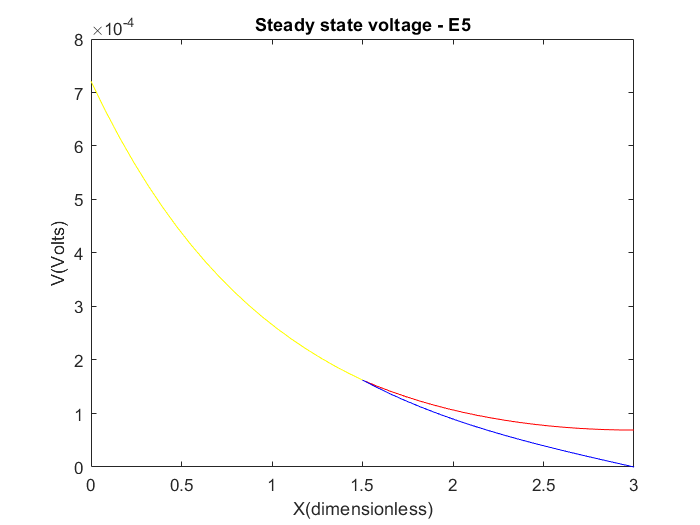


A1 = A;
A1(2,:) = [0 0 -exp(-l21) exp(l21) 0 0];
x = A1\b;
y1=linspace(0,l1,20);
y21=linspace(l1,l21,20);
y22=linspace(l1,l22,20);
v1=x(1)*exp(-y1)+x(2)*exp(y1);
v21=x(3)*exp(-y21)+x(4)*exp(y21);
v22=x(5)*exp(-y22)+x(6)*exp(y22);
plot(y1,v1,'y-',y21,v21,'r-',y22,v22,'b-');
xlabel('X(dimensionless)');
ylabel('V(Volts)');
title('Steady state voltage - E5');

### part (b)

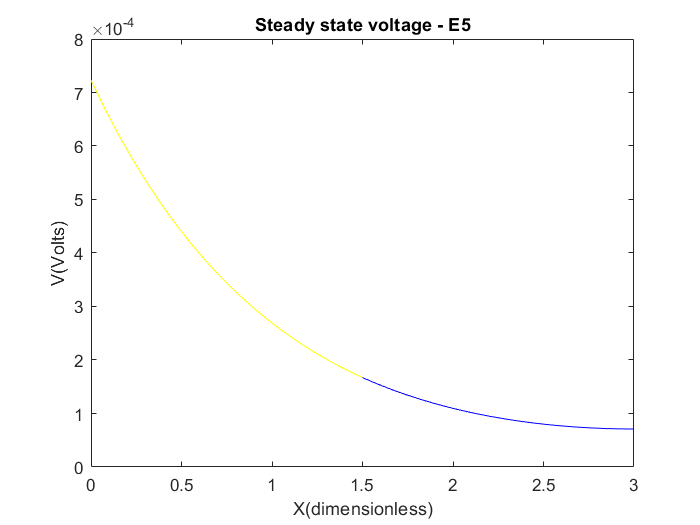

A1(3,:) = [0 0 0 0 -exp(-l22) exp(l22)];
x = A1\b;
y1=linspace(0,l1,20);
y21=linspace(l1,l21,20);
y22=linspace(l1,l22,20);
v1=x(1)*exp(-y1)+x(2)*exp(y1);
v21=x(3)*exp(-y21)+x(4)*exp(y21);
v22=x(5)*exp(-y22)+x(6)*exp(y22);
plot(y1,v1,'y-',y21,v21,'r-',y22,v22,'b-');
xlabel('X(dimensionless)');
ylabel('V(Volts)');
title('Steady state voltage - E5');

### part (c)

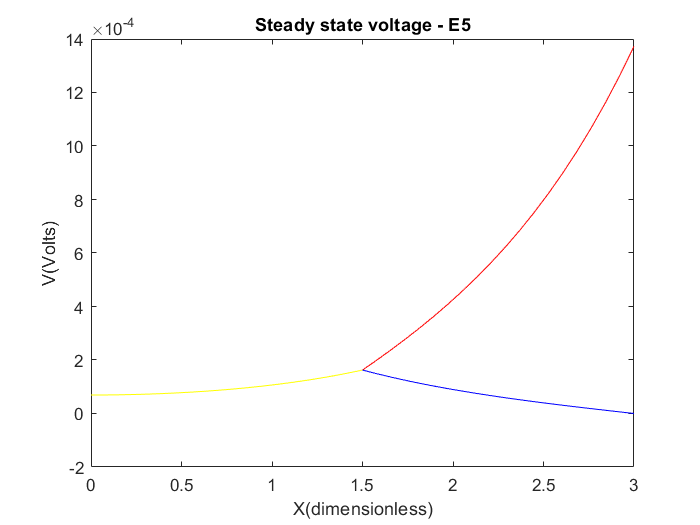

A(2,:) = [0 0 -exp(-l21) exp(l21) 0 0];
b(1) = 0; 
b(2) = rl21*iapp;
x=A\b;
y1=linspace(0,l1,20);
y21=linspace(l1,l21,20);
y22=linspace(l1,l22,20);
v1=x(1)*exp(-y1)+x(2)*exp(y1);
v21=x(3)*exp(-y21)+x(4)*exp(y21);
v22=x(5)*exp(-y22)+x(6)*exp(y22);
plot(y1,v1,'y-',y21,v21,'r-',y22,v22,'b-');
xlabel('X(dimensionless)');
ylabel('V(Volts)');
title('Steady state voltage - E5');

### part (d)

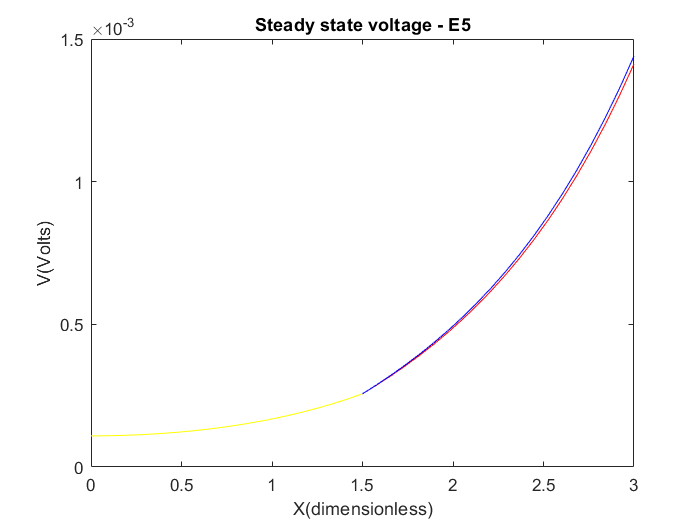

b(3) = rl22*iapp;
x=A\b;
y1=linspace(0,l1,20);
y21=linspace(l1,l21,20);
y22=linspace(l1,l22,20);
v1=x(1)*exp(-y1)+x(2)*exp(y1);
v21=x(3)*exp(-y21)+x(4)*exp(y21);
v22=x(5)*exp(-y22)+x(6)*exp(y22);
plot(y1,v1,'y-',y21,v21,'r-',y22,v22,'b-');
xlabel('X(dimensionless)');
ylabel('V(Volts)');
title('Steady state voltage - E5');

### What is the meaning of the positive right hand sides of 𝑑𝑉21/𝑑𝑋|𝑋=𝐿21 and 𝑑𝑉22/𝑑𝑋|𝑋=𝐿22 in 2(c) and 2(d)?

The membrane voltage gradient is the rate of change of the membrane voltage with respect to distance. In the case of the daughter branches, the membrane voltage gradient is positive at the rightmost nodes because the membrane voltage is increasing with respect to distance from the node. This is because the rightmost nodes of the daughter branches are transmitting an electrical impulse to another neuron or branch.

The electrical impulse is a wave of depolarization that travels down the axon of a neuron. When the impulse reaches the rightmost node of a daughter branch, it causes the membrane voltage at that node to depolarize. This depolarization then spreads to the rest of the daughter branch, causing the membrane voltage to increase with respect to distance from the node.

The increase in membrane voltage at the rightmost nodes of the daughter branches is what causes the voltage gradient to be positive at those nodes. This positive voltage gradient helps to ensure that the electrical impulse is transmitted efficiently from the parent branch to the daughter branches.

# Question 6

% Question 6
% electrical constants and derived quantities for typical 
% mammalian dendrite

% Dimensions of compartments

d1 = 75e-4; 			% cm
%d21 = 30e-4; 			% cm
%d22 = 15e-4; 			% cm
d21 = 47.2470e-4;       % E9 cm
d22 = d21;               % E9 cm

l1 = 1.5;			% dimensionless
l21 = 3.0;			% dimensionless
l22 = 3.0;			% dimensionless

% Electrical properties of compartments

Rm = 6e3;			% Ohms cm^2
Rc = 90;			% Ohms cm
Rs = 1e6;			% Ohms

c1 = 2*(Rc*Rm)^(1/2)/pi;

rl1 = c1*d1^(-3/2);		% Ohms
rl21 = c1*d21^(-3/2);		% Ohms
rl22 = c1*d22^(-3/2);		% Ohms


% Applied current

iapp = 1e-9; 	% Amps

% Coefficient matrices

A = [1 -1 0 0 0 0;
     0 0 exp(-l21) exp(l21) 0 0;
     0 0 0 0 exp(-l22) exp(l22);
     exp(-l1) exp(l1) -exp(-l1) -exp(l1) 0 0;
     0 0 exp(-l1) exp(l1) -exp(-l1) -exp(l1);
     -exp(-l1) exp(l1) rl1*exp(-l1)/rl21 -rl1*exp(l1)/rl21 rl1*exp(-l1)/rl22 -rl1*exp(-l1)/rl22];

b = [rl1*iapp 0 0 0 0 0]';

### part 2(b)


A1=A;
A1(2,:) = [0 0 -exp(-l21) exp(l21) 0 0];
A1(3,:) = [0 0 0 0 -exp(-l22) exp(l22)];
x=A1\b;
y1=linspace(0,l1,20);
y21=linspace(l1,l21,20);
y22=linspace(l1,l22,20);
v1=x(1)*exp(-y1)+x(2)*exp(y1);
v21=x(3)*exp(-y21)+x(4)*exp(y21);
v22=x(5)*exp(-y22)+x(6)*exp(y22);
plot(y1,v1,'y-',y21,v21,'r-',y22,v22,'b-');
xlabel('X(dimensionless)');
ylabel('V(Volts)');
title('Steady state voltage - E5');

### part 2(d)


A(2,:) = [0 0 -exp(-l21) exp(l21) 0 0];
b(1) = 0; 
b(2) = rl21*iapp;
b(3) = rl22*iapp;
x=A\b;
y1=linspace(0,l1,20);
y21=linspace(l1,l21,20);
y22=linspace(l1,l22,20);
v1=x(1)*exp(-y1)+x(2)*exp(y1);
v21=x(3)*exp(-y21)+x(4)*exp(y21);
v22=x(5)*exp(-y22)+x(6)*exp(y22);
plot(y1,v1,'y-',y21,v21,'r-',y22,v22,'b-');
xlabel('X(dimensionless)');
ylabel('V(Volts)');
title('Steady state voltage - E5');

The fact that the graphs in 2(c) and 2(d) are continuously differentiable means that they have no sharp corners or breaks. This is important because it allows the electrical impulse to be transmitted smoothly from the parent branch to the daughter branches.

The fact that the potential difference between the two daughter branches is negligible in 2(d) means that the two daughter branches have the same voltage. This is because the electrical impulse is transmitted equally to both daughter branches.

In conclusion, both answers are correct and complementary. They provide a comprehensive explanation of the differences between the graphs in 2(b), 2(c), and 2(d).

Here is a table that summarizes the key differences between the graphs:

Graph	Continuously differentiable?	Potential difference between daughter branches

2(b)	                        No	                                                Not negligible

2(c)	                        Yes	                                                Negligible

2(d)	                        Yes	                                                Negligible